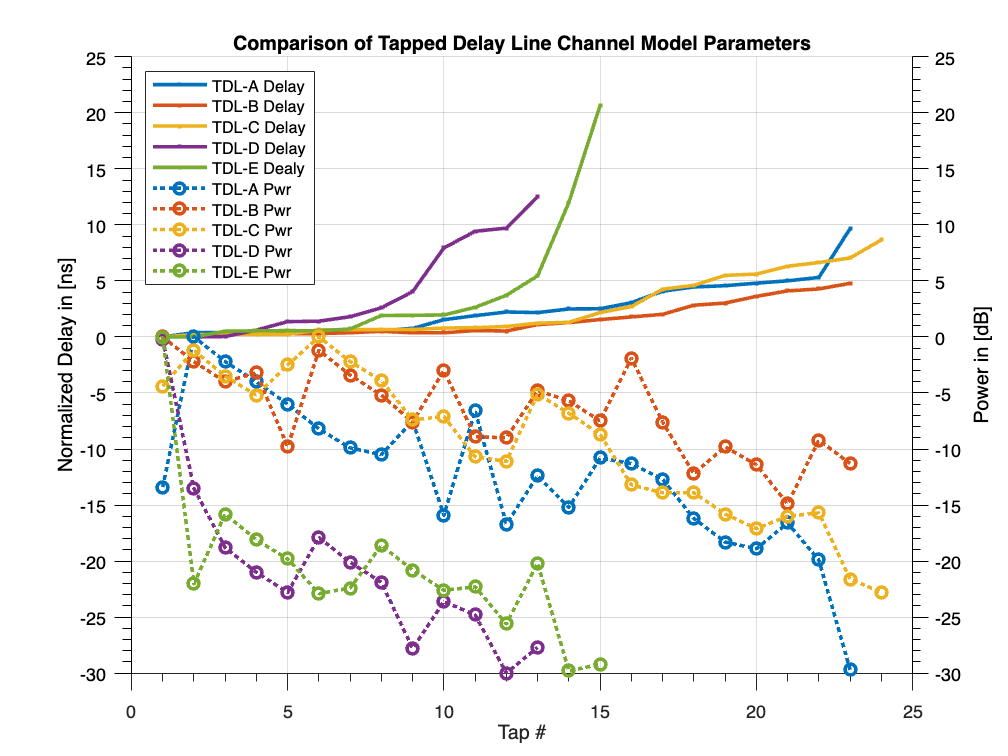

tdlA = readmatrix("TDL_A_Model.csv");
tdlB = readmatrix("TDL_B_Model.csv");
tdlC = readmatrix("TDL_C_Model.csv");
tdlD = readmatrix("TDL_D_Model.csv");
tdlE = readmatrix("TDL_E_Model.csv");

figure
grid on
hold on
yyaxis left
hYLabelL = ylabel('Normalized Delay in [ns]');

% Adjust axes properties
set(gca, 'Box', 'off', 'TickDir', 'out', 'TickLength', [.02 .02], ...
    'XMinorTick', 'on', 'YMinorTick', 'on', 'YGrid', 'on','YColor','k','ylim', [-30 25]);
aDelay = line(tdlA(:,1),tdlA(:,2));
bDelay = line(tdlB(:,1),tdlB(:,2));
cDelay = line(tdlC(:,1),tdlC(:,2));
dDelay = line(tdlD(:,1),tdlD(:,2));
eDelay = line(tdlE(:,1),tdlE(:,2));

yyaxis right
hYLabelL = ylabel(['Power in [dB]']);
% Adjust axes properties
set(gca, 'Box', 'off', 'TickDir', 'out', 'TickLength', [.02 .02], ...
    'XMinorTick', 'on', 'YMinorTick', 'on', 'YGrid', 'on', 'YColor','k','ylim', [-30 25]);
aDb = line(tdlA(:,1),tdlA(:,3));
bDb = line(tdlB(:,1),tdlB(:,3));
cDb = line(tdlC(:,1),tdlC(:,3));
dDb = line(tdlD(:,1),tdlD(:,3));
eDb = line(tdlE(:,1),tdlE(:,3));
c1=[0 0.4470 0.7410];
c2=[0.8500 0.3250 0.0980];
c3=[0.9290 0.6940 0.1250];
c4=[0.4940 0.1840 0.5560];
c5=[0.4660 0.6740 0.1880];
c6=[0.3010 0.7450 0.9330];
c7=[0.6350 0.0780 0.1840];
c8=[0 0.4470 0.7410];
c0=[0.4940 0.1840 0.5560];
set(aDelay, 'LineStyle', '-', 'Marker', '.', 'Color', c1, 'LineWidth', 2)
set(bDelay, 'LineStyle', '-', 'Marker', '.',  'Color', c2, 'LineWidth', 2)
set(cDelay, 'LineStyle', '-', 'Marker', '.',  'Color', c3, 'LineWidth', 2)
set(dDelay, 'LineStyle', '-', 'Marker', '.',  'Color', c4, 'LineWidth', 2)
set(eDelay, 'LineStyle', '-', 'Marker', '.',  'Color', c5, 'LineWidth', 2)

set(aDb, 'LineStyle', ':', 'Marker', 'o',  'Color', c1, 'LineWidth', 2)
set(bDb, 'LineStyle', ':', 'Marker', 'o',  'Color', c2, 'LineWidth', 2)
set(cDb, 'LineStyle', ':', 'Marker', 'o',  'Color', c3, 'LineWidth', 2)
set(dDb, 'LineStyle', ':', 'Marker', 'o',  'Color', c4, 'LineWidth', 2)
set(eDb, 'LineStyle', ':', 'Marker', 'o',  'Color', c5, 'LineWidth', 2)

hTitle = title('Comparison of Tapped Delay Line Channel Model Parameters');
hXLabel = xlabel('Tap #');


% Add legend
hLegend = legend([aDelay,bDelay,cDelay,dDelay,eDelay,aDb,bDb,cDb,dDb,eDb], ...
    'TDL-A Delay','TDL-B Delay','TDL-C Delay','TDL-D Delay','TDL-E Dealy','TDL-A Pwr','TDL-B Pwr','TDL-C Pwr','TDL-D Pwr','TDL-E Pwr');
set(hLegend,'Location','northwest')